%Week 12 Question 1)
clear

%importing data and converting to array
data = table2array(readtable("Week_12_Matlab_data_181220.xlsx"));

%calculating number of bins needed
N = ceil(sqrt(length(data)))

N = 8


%binning data
bins = histogram(data,N)

bins =   Histogram with properties:

             Data: [60×1 double]
           Values: [1 2 5 19 15 13 2 3]
          NumBins: 8
         BinEdges: [16 17 18 19 20 21 22 23 24]
         BinWidth: 1
        BinLimits: [16 24]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


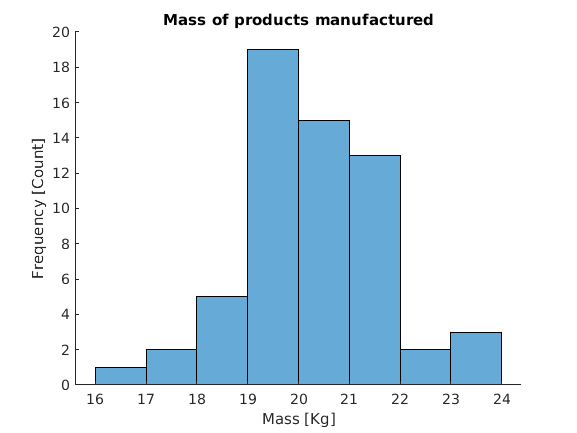


%labelling histogram
title ("Mass of products manufactured")
xlabel("Mass [Kg]")
ylabel("Frequency [Count]")

%beautifying
box off

%ensuring new graph is used
hold off


%creating cumulative frequency array
cf = [0 cumsum(bins.Values)]

cf =      0     1     3     8    27    42    55    57    60


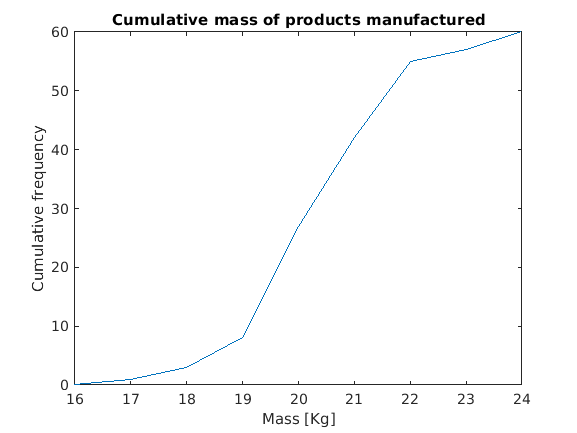


%plotting cumulative freuency graph
plot(bins.BinEdges,cf)

%labelling cumulative frequency plot
title ("Cumulative mass of products manufactured")
xlabel("Mass [Kg]")
ylabel("Cumulative frequency")

%Week 12 Question 1) (Alternative method)
clear

%importing data and converting to array
data = table2array(readtable("Week_12_Matlab_data_181220.xlsx"));

Error using readtable (line 245)
Unable to find or open 'Week_12_Matlab_data_181220.xlsx'. Check the path and filename or file permissions.


%calculating number of bins needed
N = ceil(sqrt(length(data)))

%calculating bin edges
min_data = floor(min(data))
max_data = ceil(max(data))

%creating bin edge array
edges = [min_data:1:max_data]

%getting frequencies (Creating data required for histogram
freq = histcounts(data,"BinEdges",edges)

%data_mid = [16.5:1:23.5] %one method
for i = 1:8
    data_mid(i) = (edges(i)+edges(i+1))/2;
end

%estimated mean
data_mean = sum(freq.*data_mid)/sum(freq)

%creating array for subtraction
%data_mean*ones(1,length(data_mid))

%calculating deviations
dev = data_mid - data_mean*ones(1,length(data_mean))

%squaring the deviation
sqdev = dev.^2